# **ACTIVIDAD 1. Mapeo**

**Jesús Alejandro Gómez Bautista | A01736171**

A continuación se presenta el código para mapear del sistema global al sistema local de referencia de un robot móvil y viceversa, particularmente se mapean coordenadas específicas (definidas desde el inciso A al S) para generar los marcos de referencia local y las coordenadas iniciales con el mapeo inverso.

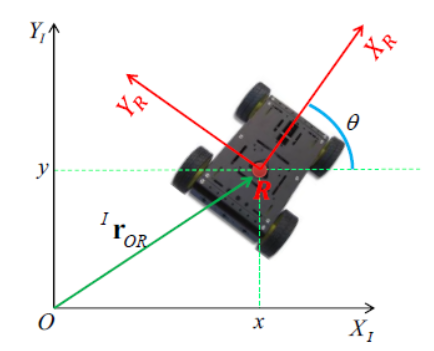

% Limpieza de pantalla
clear all 
close all
clc

tic
% Declaración de variables simbólicas
syms x(t) y(t) th(t) t 

% Grados de libertad del robot móvil

% Creamos el vector de posición
 xi_inercial = [x; y; th];
 disp('Coordenadas generalizadas');

Coordenadas generalizadas


 pretty(xi_inercial);

/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /



Aquí se crea un vector de posición `xi_inercial` en el marco de referencia inercial (o global) con las coordenadas `x`, `y` y el ángulo `th`.

% Creamos el vector de velocidades
 xip_inercial = diff(xi_inercial, t);
 disp('Velocidades generalizadas');

Velocidades generalizadas


 pretty(xip_inercial);

/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /



Se calcula la derivada del vector de posición con respecto al tiempo `t`, lo que da como resultado el vector de velocidades `xip_inercial` en el marco inercial.

% Defino mi vector de posición y matriz de rotación
P(:,:,1) = [x; y; th];

Se define un vector de posición `P` en el marco de referencia del robot. Es equivalente a `xi_inercial.`

% Matriz de rotación alrededor del eje z...
R(:,:,1) = [cos(th) -sin(th) 0;
            sin(th)  cos(th) 0;
            0        0       1];

Esta es la matriz de rotación `R` alrededor del eje `z`. Se utiliza para transformar las coordenadas del marco de referencia inercial al marco de referencia del robot. En este robot movil, nuestro eje z coincide con el centro, representación de la rotación a la hora de mover el robot mediante las llantas.

% Realizo mi transformación del marco de referencia global al local ...
xi_local = R(:,:,1)*P(:,:,1)

$$xi\_local = \left(\begin{array}{c} \cos\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)-\sin\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)\\ \cos\left(\mathrm{th}\left(t\right)\right)\,y\left(t\right)+\sin\left(\mathrm{th}\left(t\right)\right)\,x\left(t\right)\\ \mathrm{th}\left(t\right) \end{array}\right)$$

Esta línea realiza la transformación del marco de referencia inercial al marco de referencia del robot. Multiplica la matriz de rotación `R` por el vector de posición `P` para obtener el vector de posición `xi_local` en el marco de referencia del robot.

A continuación se detalla la función de las lineas de código, se usa el inciso A para facilitar la explicación, pero aplica para todos.

**Inciso A**

% Defino coordenadas inerciales para un tiempo 1
xa = -5;   % Posición inicial eje x
ya = 9;   % Posición inicial eje y
tha = -2; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_a = [xa; ya; tha];

Aquí se define el vector de posición en el marco de referencia inercial (o global) con las coordenadas y el ángulo.

Rot_a = [cos(tha) -sin(tha) 0;
         sin(tha)  cos(tha) 0;
         0         0        1];

Esta es la matriz de rotación alrededor del eje `z`. Se utiliza para transformar las coordenadas del marco de referencia inercial al marco de referencia del robot.

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_a = Rot_a*Pos_a

xi_local_a =    10.2644
    0.8012
   -2.0000


Esta línea realiza la transformación del marco de referencia inercial al marco de referencia del robot. Multiplica la matriz de rotación por el vector de posición para obtener el vector de posición en el marco de referencia del robot.

% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_a(1)^2 + xi_local_a(2)^2)

magnitud = 10.2956

Aquí se calcula la magnitud del vector resultante `xi_local_a` utilizando el teorema de Pitágoras.

% Compruebo que me devuelva el vector inercial
inv_Rot_a = inv(Rot_a);

Esta línea calcula la matriz inversa de la matriz de rotación. Esta matriz inversa se utiliza para transformar las coordenadas del marco de referencia del robot de nuevo al marco de referencia inercial.

xi_inercial_a = inv_Rot_a*xi_local_a

xi_inercial_a =    -5.0000
    9.0000
   -2.0000


Esta línea realiza la transformación del marco de referencia del robot de nuevo al marco de referencia inercial. Multiplica la matriz inversa de la rotación por el vector de posición local para obtener el vector de posición en el marco de referencia inercial.

**Inciso B**

% Defino coordenadas inerciales para un tiempo 1
xb = -3;   % Posición inicial eje x
yb = 8;   % Posición inicial eje y
thb = 63; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_b = [xb; yb; thb];
Rot_b = [cos(thb) -sin(thb) 0;
         sin(thb)  cos(thb) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_b = Rot_b*Pos_b

xi_local_b =    -4.2965
    7.3851
   63.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_b(1)^2 + xi_local_b(2)^2)

magnitud = 8.5440



% Compruebo que me devuelva el vector inercial
inv_Rot_b = inv(Rot_b);
xi_inercial_b = inv_Rot_b*xi_local_b

xi_inercial_b =     -3
     8
    63


**Inciso C**

% Defino coordenadas inerciales para un tiempo 1
xc = 5;   % Posición inicial eje x
yc = -2;   % Posición inicial eje y
thc = 90; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_c = [xc; yc; thc];
Rot_c = [cos(thc) -sin(thc) 0;
         sin(thc)  cos(thc) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_c = Rot_c*Pos_c

xi_local_c =    -0.4524
    5.3661
   90.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_c(1)^2 + xi_local_c(2)^2)

magnitud = 5.3852



% Compruebo que me devuelva el vector inercial
inv_Rot_c = inv(Rot_c);
xi_inercial_c = inv_Rot_c*xi_local_c

xi_inercial_c =     5.0000
   -2.0000
   90.0000


**Inciso D**

% Defino coordenadas inerciales para un tiempo 1
xd = 0;   % Posición inicial eje x
yd = 0;   % Posición inicial eje y
thd = 180; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_d = [xd; yd; thd];
Rot_d = [cos(thd) -sin(thd) 0;
         sin(thd)  cos(thd) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_d = Rot_d*Pos_d

xi_local_d =      0
     0
   180



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_d(1)^2 + xi_local_d(2)^2)

magnitud = 0



% Compruebo que me devuelva el vector inercial
inv_Rot_d = inv(Rot_a);
xi_inercial_d = inv_Rot_d*xi_local_d

xi_inercial_d =      0
     0
   180


**Inciso E**

% Defino coordenadas inerciales para un tiempo 1
xe = -6;   % Posición inicial eje x
ye = 3;   % Posición inicial eje y
the = -55; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_e = [xe; ye; the];
Rot_e = [cos(the) -sin(the) 0;
         sin(the)  cos(the) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_e = Rot_e*Pos_e

xi_local_e =    -3.1320
   -5.9322
  -55.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_e(1)^2 + xi_local_e(2)^2)

magnitud = 6.7082



% Compruebo que me devuelva el vector inercial
inv_Rot_e = inv(Rot_e);
xi_inercial_e = inv_Rot_e*xi_local_e

xi_inercial_e =    -6.0000
    3.0000
  -55.0000


**Inciso F**

% Defino coordenadas inerciales para un tiempo 1
xf = 10;   % Posición inicial eje x
yf = -2;   % Posición inicial eje y
thf = 45; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_f = [xf; yf; thf];
Rot_f = [cos(thf) -sin(thf) 0;
         sin(thf)  cos(thf) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_f = Rot_f*Pos_f

xi_local_f =     6.9550
    7.4584
   45.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_f(1)^2 + xi_local_f(2)^2)

magnitud = 10.1980



% Compruebo que me devuelva el vector inercial
inv_Rot_f = inv(Rot_f);
xi_inercial_f = inv_Rot_f*xi_local_f

xi_inercial_f =    10.0000
   -2.0000
   45.0000


**Inciso G**

% Defino coordenadas inerciales para un tiempo 1
xg = 9;   % Posición inicial eje x
yg = 1;   % Posición inicial eje y
thg = 88; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_g = [xg; yg; thg];
Rot_g = [cos(thg) -sin(thg) 0;
         sin(thg)  cos(thg) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_g = Rot_g*Pos_g

xi_local_g =     8.9590
    1.3180
   88.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_g(1)^2 + xi_local_g(2)^2)

magnitud = 9.0554



% Compruebo que me devuelva el vector inercial
inv_Rot_g = inv(Rot_g);
xi_inercial_g = inv_Rot_g*xi_local_g

xi_inercial_g =     9.0000
    1.0000
   88.0000


**Inciso H**

% Defino coordenadas inerciales para un tiempo 1
xh = 5;   % Posición inicial eje x
yh = 2;   % Posición inicial eje y
thh = 33; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_h = [xh; yh; thh];
Rot_h = [cos(thh) -sin(thh) 0;
         sin(thh)  cos(thh) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_h = Rot_h*Pos_h

xi_local_h =    -2.0662
    4.9730
   33.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_h(1)^2 + xi_local_h(2)^2)

magnitud = 5.3852



% Compruebo que me devuelva el vector inercial
inv_Rot_h = inv(Rot_h);
xi_inercial_h = inv_Rot_h*xi_local_h

xi_inercial_h =     5.0000
    2.0000
   33.0000


**Inciso I**

% Defino coordenadas inerciales para un tiempo 1
xi = -1;   % Posición inicial eje x
yi = -1;   % Posición inicial eje y
thi = 21; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_i = [xi; yi; thi];
Rot_i = [cos(thi) -sin(thi) 0;
         sin(thi)  cos(thi) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_i = Rot_i*Pos_i

xi_local_i =     1.3844
   -0.2889
   21.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_i(1)^2 + xi_local_i(2)^2)

magnitud = 1.4142



% Compruebo que me devuelva el vector inercial
inv_Rot_i = inv(Rot_i);
xi_inercial_i = inv_Rot_i*xi_local_i

xi_inercial_i =    -1.0000
   -1.0000
   21.0000


**Inciso J**

% Defino coordenadas inerciales para un tiempo 1
xj = 6;   % Posición inicial eje x
yj = 4;   % Posición inicial eje y
thj = -40; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_j = [xj; yj; thj];
Rot_j = [cos(thj) -sin(thj) 0;
         sin(thj)  cos(thj) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_j = Rot_j*Pos_j

xi_local_j =    -1.0212
   -7.1384
  -40.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_j(1)^2 + xi_local_j(2)^2)

magnitud = 7.2111



% Compruebo que me devuelva el vector inercial
inv_Rot_j = inv(Rot_j);
xi_inercial_j = inv_Rot_j*xi_local_j

xi_inercial_j =      6
     4
   -40


**Inciso k**

% Defino coordenadas inerciales para un tiempo 1
xk = 5;   % Posición inicial eje x
yk = 7;   % Posición inicial eje y
thk = 72; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_k = [xk; yk; thk];
Rot_k = [cos(thk) -sin(thk) 0;
         sin(thk)  cos(thk) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_k = Rot_k*Pos_k

xi_local_k =    -6.6130
   -5.5016
   72.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_k(1)^2 + xi_local_k(2)^2)

magnitud = 8.6023



% Compruebo que me devuelva el vector inercial
inv_Rot_k = inv(Rot_k);
xi_inercial_k = inv_Rot_k*xi_local_k

xi_inercial_k =     5.0000
    7.0000
   72.0000


**Inciso L**

% Defino coordenadas inerciales para un tiempo 1
xl = 7;   % Posición inicial eje x
yl = 7;   % Posición inicial eje y
thl = 30; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_l = [xl; yl; thl];
Rot_l = [cos(thl) -sin(thl) 0;
         sin(thl)  cos(thl) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_l = Rot_l*Pos_l

xi_local_l =     7.9960
   -5.8365
   30.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_l(1)^2 + xi_local_l(2)^2)

magnitud = 9.8995



% Compruebo que me devuelva el vector inercial
inv_Rot_l = inv(Rot_l);
xi_inercial_l = inv_Rot_l*xi_local_l

xi_inercial_l =     7.0000
    7.0000
   30.0000


**Inciso M**

% Defino coordenadas inerciales para un tiempo 1
xm = 11;   % Posición inicial eje x
ym = -4;   % Posición inicial eje y
thm = 360; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_m = [xm; ym; thm];
Rot_m = [cos(thm) -sin(thm) 0;
         sin(thm)  cos(thm) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_m = Rot_m*Pos_m

xi_local_m =     0.7151
   11.6828
  360.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_m(1)^2 + xi_local_m(2)^2)

magnitud = 11.7047



% Compruebo que me devuelva el vector inercial
inv_Rot_m = inv(Rot_m);
xi_inercial_m = inv_Rot_m*xi_local_m

xi_inercial_m =     11
    -4
   360


**Inciso N**

% Defino coordenadas inerciales para un tiempo 1
xn = 20;   % Posición inicial eje x
yn = 5;   % Posición inicial eje y
thn = 270; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_n = [xn; yn; thn];
Rot_n = [cos(thn) -sin(thn) 0;
         sin(thn)  cos(thn) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_n = Rot_n*Pos_n

xi_local_n =    20.5679
    1.4010
  270.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_n(1)^2 + xi_local_n(2)^2)

magnitud = 20.6155



% Compruebo que me devuelva el vector inercial
inv_Rot_n = inv(Rot_n);
xi_inercial_n = inv_Rot_n*xi_local_n

xi_inercial_n =    20.0000
    5.0000
  270.0000


**Inciso Ñ**

% Defino coordenadas inerciales para un tiempo 1
xnn = 10;   % Posición inicial eje x
ynn = 9;   % Posición inicial eje y
thnn = 345; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_nn = [xnn; ynn; thnn];
Rot_nn = [cos(thnn) -sin(thnn) 0;
         sin(thnn)  cos(thnn) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_nn = Rot_nn*Pos_nn

xi_local_nn =    13.2868
    2.1118
  345.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_nn(1)^2 + xi_local_nn(2)^2)

magnitud = 13.4536



% Compruebo que me devuelva el vector inercial
inv_Rot_nn = inv(Rot_nn);
xi_inercial_nn = inv_Rot_nn*xi_local_nn

xi_inercial_nn =     10
     9
   345


**Inciso O**

% Defino coordenadas inerciales para un tiempo 1
xo = -9;   % Posición inicial eje x
yo = -8;   % Posición inicial eje y
tho = 8; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_o = [xo; yo; tho];
Rot_o = [cos(tho) -sin(tho) 0;
         sin(tho)  cos(tho) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_o = Rot_o*Pos_o

xi_local_o =     9.2244
   -7.7402
    8.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_o(1)^2 + xi_local_o(2)^2)

magnitud = 12.0416



% Compruebo que me devuelva el vector inercial
inv_Rot_o = inv(Rot_o);
xi_inercial_o = inv_Rot_o*xi_local_o

xi_inercial_o =     -9
    -8
     8


**Inciso P**

% Defino coordenadas inerciales para un tiempo 1
xp = 1;   % Posición inicial eje x
yp = 1;   % Posición inicial eje y
thp = 60; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_p = [xp; yp; thp];
Rot_p = [cos(thp) -sin(thp) 0;
         sin(thp)  cos(thp) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_p = Rot_p*Pos_p

xi_local_p =    -0.6476
   -1.2572
   60.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_p(1)^2 + xi_local_p(2)^2)

magnitud = 1.4142



% Compruebo que me devuelva el vector inercial
inv_Rot_p = inv(Rot_p);
xi_inercial_p = inv_Rot_p*xi_local_p

xi_inercial_p =      1
     1
    60


**Inciso Q**

% Defino coordenadas inerciales para un tiempo 1
xq = 3;   % Posición inicial eje x
yq = 1;   % Posición inicial eje y
thq = -30; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_q = [xq; yq; thq];
Rot_q = [cos(thq) -sin(thq) 0;
         sin(thq)  cos(thq) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_q = Rot_q*Pos_q

xi_local_q =    -0.5253
    3.1183
  -30.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_q(1)^2 + xi_local_q(2)^2)

magnitud = 3.1623



% Compruebo que me devuelva el vector inercial
inv_Rot_q = inv(Rot_q);
xi_inercial_q = inv_Rot_q*xi_local_q

xi_inercial_q =     3.0000
    1.0000
  -30.0000


**Inciso R**

% Defino coordenadas inerciales para un tiempo 1
xr = 15;   % Posición inicial eje x
yr = 2;   % Posición inicial eje y
thr = 199; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_r = [xr; yr; thr];
Rot_r = [cos(thr) -sin(thr) 0;
         sin(thr)  cos(thr) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_r = Rot_r*Pos_r

xi_local_r =    -5.3108
  -14.1702
  199.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_r(1)^2 + xi_local_r(2)^2)

magnitud = 15.1327



% Compruebo que me devuelva el vector inercial
inv_Rot_r = inv(Rot_r);
xi_inercial_r = inv_Rot_r*xi_local_r

xi_inercial_r =     15
     2
   199


**Inciso S**

% Defino coordenadas inerciales para un tiempo 1
xs = -10;   % Posición inicial eje x
ys = 0;   % Posición inicial eje y
ths = 300; % Orientación inicial del robot

% Defino mi vector de posición y mi matriz de rotación para un tiempo 1
Pos_s = [xs; ys; ths];
Rot_s = [cos(ths) -sin(ths) 0;
         sin(ths)  cos(ths) 0;
         0         0        1];

% Realizo mi transnformación del marco de referencia inercial al local ...
xi_local_s = Rot_s*Pos_s

xi_local_s =     0.2210
    9.9976
  300.0000



% Obtengo la magnitud del vector resultante
magnitud = sqrt(xi_local_s(1)^2 + xi_local_s(2)^2)

magnitud = 10



% Compruebo que me devuelva el vector inercial
inv_Rot_s = inv(Rot_s);
xi_inercial_s = inv_Rot_s*xi_local_s

xi_inercial_s =   -10.0000
   -0.0000
  300.0000


**Conclusiones**

Este script es una demostración fundamental de cómo los robots pueden interactuar con su entorno entendiendo su posición tanto en términos globales como locales, permitiendo un movimiento preciso y la ejecución de tareas dentro de un espacio definido. Es un claro ejemplo de cómo conceptos matemáticos como las matrices de rotación se aplican en robótica para fines prácticos como la localización y el mapeo.